load officemap.mat;

rosshutdown;

Shutting down global node /matlab_global_node_18986 with NodeURI http://192.168.200.1:3472/ and MasterURI http://192.168.200.128:11311.



ipaddress = '192.168.200.128'; 
rosinit(ipaddress,11311);

Initializing global node /matlab_global_node_34253 with NodeURI http://192.168.200.1:3490/ and MasterURI http://192.168.200.128:11311.



odometryModel = odometryMotionModel;
odometryModel.Noise = [0.5 0.5 0.5 0.5]; 
% 로봇의 회전운동과 직선운동에 있어서의 불확실함을 정의하는 것
% 해당 값이 높을수록 odometry 측정값을 이용해서 파티클들을 더 넓게 퍼뜨릴 수 있음

rangeFinderModel = likelihoodFieldSensorModel; % likelihood field sensor model 객체 생성
rangeFinderModel.SensorLimits = [0.45 8]; % 센서의 최소인식 범위와 최대인식 범위
rangeFinderModel.Map = map; % SLAM을 통해 작성한 Occupancy grid map

% rostf : frame들 사이의 translation을 의미
% 이 부분의  ROS의 TF TREE를 사용하기에 CAN 통신에 사용할 수 없다고 판단하여 이 부분을 사용하지 않도록 변경
% 따라서 ROS TF TREE를 사용하지 않도록 필요한 값을 얻을 수 있도록 상수값으로 초기화.
%{
tftree = rostf;
waitForTransform(tftree,'/base_link','/base_scan'); % /base_link : 로봇 자체의 위치를 나타내는 frame, % /base_scan : 라이다 frame
sensorTransform = getTransform(tftree,'/base_link', '/base_scan'); 

% ros는 orientation(rotation)을 quaternion이라는 수학적 개념으로 정의함.
% 따라서 tf를 통해 얻은 회전값을 오일러 회전각으로 변환하여 라이다의 z축에서의 회전각을 알 수 있음.
laserQuat = [sensorTransform.Transform.Rotation.W sensorTransform.Transform.Rotation.X ...
    sensorTransform.Transform.Rotation.Y sensorTransform.Transform.Rotation.Z];
laserRotation = quat2eul(laserQuat, 'ZYX');
%}

% |SensorPose|는 range 센서 위치를 차량의 frame 위치와 비교했을 떄의 상대적인 값을 의미
% 따라서 위에서 생성한 ros tf의 개념을 사용
% [x y theta], theta는 z축에서의 회전각을 의미.위에서 계산한 laserRotation 값을 사용
% rangeFinderModel.SensorPose = [sensorTransform.Transform.Translation.X sensorTransform.Transform.Translation.Y laserRotation(1)];

% 하지만 이는 라이다와 프레임간의 위치와 각도를 비교한 상수값이기에 같은 모델이라면 항상 같은 값을 의미. 따라서 아래처럼 직접 지정해도 가능한 것으로 판단됨.
rangeFinderModel.SensorPose = [-0.0320 0 0.1720 ]; % 로봇의 라이다 센서위치를 로봇의 프레임 위치와 비교했을 때의 차이값을 의미. [x y theta] 형태

laserSub = rossubscriber('/scan');
odomSub = rossubscriber('/odom');

[velPub,velMsg] = rospublisher('/cmd_vel','geometry_msgs/Twist');

amcl = monteCarloLocalization; % 몬테카를로 위치추정 객체 생성
amcl.UseLidarScan = true; % 라이다 데이터를 사용할 것이기에 true로 설정

amcl.MotionModel = odometryModel; % 위에서 생성한 odometryModel을 몬테카를로 객체의 속성으로 할당
amcl.SensorModel = rangeFinderModel; % 위에서 생성한 Likelihood field sensor model을 몬테카를로 객체의 속성으로 할당

amcl.UpdateThresholds = [0.01 ,0.01 ,0.05]; % [x y theta] 형태, 해당 값만큼 위치가 변했을 경우에만 로봇의 pose를 update함
amcl.ResamplingInterval = 3; % 파티클들을 재배열하는 간격을 의미

amcl.ParticleLimits = [500 50000]; % 맵에 존재하는 최소 파티클 수와 최대 파티클 수 를 의미
amcl.GlobalLocalization = true; % 현재 위치 추정값을 초기값으로 할당하지 않을 경우에 젼역탐색을 수행, 따라서 맵 전체에 파티클들을 흩뿌리고 수렴시키는 과정을 수행

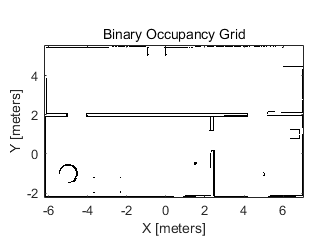

visualizationHelper = ExampleHelperAMCLVisualization(map);


wanderHelper = new_Wanderer_2(laserSub, velPub, velMsg);
% 로봇이 라이다 데이터를 이용해서 vfh 알고리즘을 이용햇 장애물을 회피하면서 이동하는 함수
% 이 함수의 인자 중 'sensorTransform'이라는 인자를 할당해줘야 하는데 이 인자는 ROS에서 지원해주는 패키지 함수이기에
% CAN 통신에서는 사용이 불가능할 것으로 사료되어 따로 장애물들을 회피하며 기동할 수 있는 코드를 짜야할 것

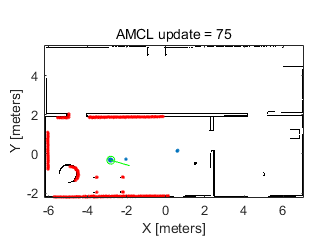

numUpdates = 75; % 로봇의 pose를 업데이트를 수행할 횟수를 의미
i = 0;

while i < numUpdates

    % lidar scan 값과 odometry 값을 불러옴
    scanMsg = receive(laserSub);
    odompose = odomSub.LatestMessage;
    
    % lidarScan 객체를 생성
    scan = lidarScan(scanMsg);
    
    % odometry를 통해 받은 message를 이용해서 로봇의 위치를 계산. [x,y,yaw] 형태.
    % odometry를 통해 얻은 회전값을 오일러 회전각으로 변환하여 odometry의 z축에서의 회전각을 알 수 있음.
    % CAN에 맞게 변형 필요
    odomQuat = [odompose.Pose.Pose.Orientation.W, odompose.Pose.Pose.Orientation.X, odompose.Pose.Pose.Orientation.Y, odompose.Pose.Pose.Orientation.Z];
    odomRotation = quat2eul(odomQuat);
    pose = [odompose.Pose.Pose.Position.X, odompose.Pose.Pose.Position.Y odomRotation(1)];
    
    % 로봇의 위치를 업데이트
    [isUpdated,estimatedPose, estimatedCovariance] = amcl(pose, scan);
    
    % 로봇이 계속 이동
    % 해당 사이트를 참고했는데 해당 클래스의 wander함수에는 ros 패키지의 tf tree가 사용됨
    % 또한 이 tf tree는 위에서 추정한 라이다와 프레임 간의 상대적인 위치를 나타내는 상수값과 달리 수행할 때마다 값이 바뀌는 변수형태
    
    wander(wanderHelper);

    
    % 만약 업데이트가 성공적으로 수행 되었다면
    % 로봇의 위치와 particle들 그리고 라이다 스캔을 나타내는 plot을 생성
    if isUpdated
        i = i + 1;
        plotStep(visualizationHelper, amcl, estimatedPose, scan, i)
    end
    
end

stop(wanderHelper);
disp(estimatedPose);

   -2.8160   -0.3193   -0.2850




rosshutdown;

Shutting down global node /matlab_global_node_34253 with NodeURI http://192.168.200.1:3490/ and MasterURI http://192.168.200.128:11311.
